# MATLAB Companion Script for *Machine Learning* ex5 (Optional)

## Introduction

Coursera's* Machine Learning* was designed to provide you with a greater understanding of machine learning algorithms- what they are, how they work, and where to apply them. You are also shown techniques to improve their performance and to address common issues. As is mentioned in the course, there are many tools available that allow you to use machine learning algorithms *without* having to implement them yourself. This Live Script was created by MathWorks to help *Machine Learning* students explore the data analysis and machine learning tools available in MATLAB.

## FAQ

**Who is this intended for?**

- This script is intended for students using MATLAB Online who have completed ex5 and want to learn more about the corresponding machine learning tools in MATLAB.

**How do I use this script?**

- In the sections that follow, read the information provided about the data analysis and machine learning tools in MATLAB, then run the code in each section and examine the results. You may also be presented with instructions for using a MATLAB machine learning app. This script should be located in the ex5 folder which should be set as your Current Folder in MATLAB Online.

**Can I use the tools in this companion script to complete the programming exercises?**

- No. Most algorithm steps implemented in the programming exercises are handled automatically by MATLAB machine learning functions. Additionally, the final results will be similar, but not identical, to those in the programming exercises due to differences in implementation, parameter settings, and randomization.

**Where can I obtain help with this script or report issues?**

- As this script is not part of the original course materials, please direct any questions, comments, or issues to the *MATLAB Help* discussion forum.

# Regularized Linear Regression and Cross-Validation

In this Live Script, we will use functions and apps from the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html) to partition data into training and validation sets and determine optimal regularization strengths using cross-validation.

## Files needed for this script

- `ex5data1.mat` - Waterflow dataset

# Data Partitioning and High Bias and High Variance Models

Many functions used to train models in the Statistics and Machine Learning Toolbox are equipped to partition a dataset into training and cross-validation sets automatically. However, creating a fixed partition is often helpful for reproducibility of results, or when comparing the performance of several different algorithms. These partitions can also be useful when training models using functions for building and training simpler models like `fitlm` and `fitglm` which do not partition data automatically or provide options for validation. In this section we will use the `cvpartition` function to partition the water flow data from ex5.

## Load the data

Recall that the data contained in `ex5data1.mat` is divided into three sets:

- A **training** set to train the model

- A **cross-validation** set to determine the regularization parameter

- A **test** set to evaluate performance. 

In MATLAB, there is no need to store training and validation sets in separate variables. Run the code below to combine the training, test, and validation sets into a single `table` variable, `data`, and clear the original variables.

clear;
load ex5data1.mat;
LevelChange = [X;Xtest;Xval];
Outflow = [y;ytest;yval];
data = table(LevelChange,Outflow);
clearvars -except data;

## Partition the dataset

Next we will use the [`cvpartition`](https://www.mathworks.com/help/stats/cvpartition.html) function to partition the water flow data into a training set with 12 examples (for direct comparison with your results from ex5) and validation set with the remaining data. The result will be a [`cvpartition`](https://www.mathworks.com/help/stats/cvpartition-class.html) variable that contains the partition information and the indicies of corresponding to the two sets. This variable can then be passed to MATLAB machine learning functions along with the original dataset for model training and validation. Alternatively, we can also extract a binary vector corresponding to the training and validation examples from the partition variable using the `training` and `test` functions, as demonstrated below, for use with functions like `fitlm` and `fitglm`. 

m = height(data); % height() returns the number of rows in a table
c = cvpartition(m,'HoldOut',m-12) % Choose 12 training examples

c = Hold-out cross validation partition
   NumObservations: 54
       NumTestSets: 1
         TrainSize: 12
          TestSize: 42

tinds = training(c) % Training indices

tinds = 54×1 logical array
   0
   0
   0
   0
   0
   1
   0
   1
   1
   0


**Note**: In the terminology of the Statistics and Machine Learning Toolbox, 'test' sets correspond to the 'validation' sets described in class. A 'test' set as described in the course - data not used in training OR validation - would still need to be stored in a separate `table` or matrix.

## Fit a high bias and high variance model to the training data

As in ex5, we will fit a linear model as an example of a high bias model, followed by an 8th degree polynomial model as a high variance model example. The code below uses `fitlm` to train the models using then plots the results. If you are interested, you can re-run both this section and the previous one to visualize the effect that the small training set size and random partition selections have on high bias/variance models. 

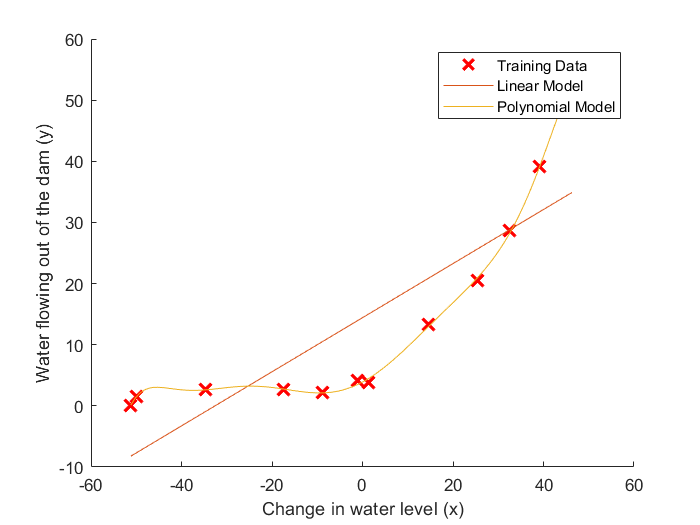

% Train the models
highBiasMdl = fitlm(data(tinds,[1,2]));
HighVarMdl = fitlm(data(tinds,[1 2]),'poly8');
% Plot the model and training data
xplot = linspace(min(data.LevelChange(tinds)),max(data.LevelChange(tinds)))';
y1 = predict(highBiasMdl,xplot);
y2 = predict(HighVarMdl,xplot);
figure; hold on;
plot(data.LevelChange(tinds),data.Outflow(tinds),'rx','MarkerSize',10,'LineWidth',2);
plot(xplot,y1); plot(xplot,y2); hold off;
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
legend({'Training Data','Linear Model','Polynomial Model'})

# Regularized Linear Regression using `fitrlinear`

As discussed in ex5, the linear model is too simple to accurately reflect the complexity of the water flow data, while polynomial model tends to overfit the data and changes dramatically depending on the partition. In ex5 you found that the performance of the polynomial model can be improved on new data by adding regularization during training. Cross validation was then used to determine the 'best' value of the regularization parameter, $\lambda$. In this section, we use the [`fitrlinear`](https://www.mathworks.com/help/stats/fitrlinear.html) function to fit a regularized polynomial model to the data. Like `fitclinear` (used in the companion script for ex2), `fitrlinear` is designed to train models with a large number of variables and it also includes options for adding regularization. 

## Load and normalize the data

The code below will reload the data and create a (normalized) polynomial feature matrix `X` by combining the training and validation sets as before. As with `fitclinear`, `fitrlinear` requires feature and response data as numeric arrays (i.e. not in a `table`). Since we found that the 8th degree polynomial model was subject to very high variance in the previous section, we also limit the polynomial degree to 4 to outline a more realistic model example.

load ex5data1.mat;
LevelChange = [X;Xtest;Xval];
Outflow = [y;ytest;yval];
clearvars -except LevelChange Outflow;
mu = mean(LevelChange);
sd = std(LevelChange);
LevelChange = ((LevelChange-mu)/sd).^(1:4);

## Partition the data

In this section we will let `fitrlinear` partition the data automatically for us. We also provide code in this section and the next one to create the corresponding model using a `cvpartition` variable as comments.  Run the code below to select the proportion of data to hold out during training for validation purposes. 

holdout = 0.35;
% c = cvpartiton(length(LevelChange),'HoldOut',holdout)

## Fit linear regression models using multiple $\lambda$ values

In the companion script for ex3, we trained a regularized model by passing a single regularization value `lambda` to `fitclinear` using the `'Lambda'` option. We can also use this option with `fitrlinear`. However, by passing *a vector* of $\lambda$ values to these functions, a separate model will automatically be trained for each $\lambda$ value. Run the code below to create a vector of $\lambda$ values and train the regression models for each $\lambda$. When using multiple regularization values with `fitrlinear`, the trained models will be returned in a [`RegressionPartitionedLinear`](https://www.mathworks.com/help/stats/regressionpartitionedlinear-class.html) model variable instead of a [`RegressionLinear`](https://www.mathworks.com/help/stats/regressionlinear-class.html) variable which is discussed in the next section.

lambda = [0 0.01 0.03 0.1 0.3 1];
partMdl = fitrlinear(LevelChange,Outflow,'Learner','leastsquares','Regularization','Ridge','Lambda',lambda,'HoldOut',holdout)

partMdl =   classreg.learning.partition.RegressionPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 54
                  KFold: 1
              Partition: [1×1 cvpartition]
      ResponseTransform: 'none'


  Properties, Methods


% partMdl = fitrlinear(LevelChange,Outflow,'Learner','leastsquares','Regularization','Ridge','Lambda',lambda,'CVPartition',c)

## Working with partitioned model variables

The individual regression models are contained in the `Trained` property of a `RegressionPartitionedLinear` variable. In the case of hold-out cross validation, the `Trained` property is a cell array which contains a single `RegressionLinear` (or `ClassificationLinear` when using `fitclinear`) model variable. This variable contains the trained models for each regularization value $\lambda$. The model partition that was used during training and validation is found in the `Partition` property. 

    The model coefficients ($\theta$) are found in the $p\times l$  matrix `Beta` and the $1\times l$ vector `bias`, where $p$ is the number of model coefficients (4 in the current example) and $l$ is the number of $\lambda$ values (6). The columns of `Beta` therefore correspond to coefficients for a particular model. The model coefficients and the corresponding lambda values are displayed below for comparison. Run the code below to extract the trained model variable, the partition variable, and the model coefficients. Do the increasing regularization values have the expected effect on the size of the coefficients and bias?

polyRegMdl = partMdl.Trained{1}

polyRegMdl =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [4×6 double]
                 Bias: [6.0989 6.2732 6.5156 6.9226 7.3051 7.7941]
               Lambda: [0 0.0100 0.0300 0.1000 0.3000 1]
              Learner: 'leastsquares'


  Properties, Methods


c = partMdl.Partition

c = Hold-out cross validation partition
   NumObservations: 54
       NumTestSets: 1
         TrainSize: 36
          TestSize: 18

[polyRegMdl.Bias; polyRegMdl.Beta]

ans =     6.0989    6.2732    6.5156    6.9226    7.3051    7.7941
    4.9821    4.7297    4.3413    3.5722    2.7710    2.0245
    4.8264    4.2836    3.5409    2.3616    1.4785    0.9421
    3.4473    3.5396    3.6776    3.9185    4.0251    3.6429
    1.2267    1.4133    1.6650    2.0434    2.2521    2.1378


lambda

lambda =          0    0.0100    0.0300    0.1000    0.3000    1.0000


## Evaluate model performance and select models using `kfoldLoss` and `selectModels`

Instead of using learning curves to detect high bias or variance issues, followed validation curves to determine the optimal regularization parameter value, we will use the [`kfoldLoss`](https://www.mathworks.com/help/stats/regressionpartitionedlinear.kfoldloss.html)`*` function to compute the cost of all models in the partitioned model variable using the validation set. We then extract the individual model with the lowest cost using the [`selectModels`](https://www.mathworks.com/help/stats/regressionlinear.selectmodels.html) function. The result will be a `RegressionLinear` model variable corresponding to the best model as found by cross-validation.

valCost = kfoldLoss(partMdl)
[~,bestidx] = min(valCost)
fprintf('The best value of lambda found by cross-validation is: %g', lambda(bestidx))
bestRegMdl = selectModels(polyRegMdl,bestidx)

*K-fold cross validation is discussed at the end of this Live Script. K-fold validation with 1 fold is equivalent to hold-out validation.

## Predict the response for all models and visualize the results

Run the code below to plot the training data, validation data, and the models for each $\lambda$. Note, when using the `predict` function along with a model variable containing multiple models (coefficient sets), `predict` will return a response *matrix*, where the $i$th column of the matrix corresponds to the prediction using the *i*th model (trained with the $i$th regularization value).

% Extract the training and validation data
xtrain = LevelChange(training(c),1); 
ytrain = Outflow(training(c));
xval = LevelChange(test(c),1); 
yval = Outflow(test(c));
% Plot the data and models
xplot = linspace(min(LevelChange(:,1)),max(LevelChange(:,1)))';
xplot = xplot.^(1:4);
Y = predict(polyRegMdl,xplot);
figure; hold on;
plot(xtrain*sd+mu,ytrain,'go','MarkerSize',10);
plot(xval*sd+mu,yval,'LineStyle','none','Marker','square','MarkerSize',10);
plt = plot(xplot(:,1)*sd+mu,Y,'--'); hold off;
set(plt,{'Color'},num2cell(jet(length(lambda)),2));
set(plt(bestidx),'LineStyle','-','LineWidth',2);
ylim([min(Outflow) max(Outflow)]);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
legend(['Training','Validation',cellstr("lambda = "+string(lambda))],'Location','NorthWest')
title(sprintf('Best lambda = %g',lambda(bestidx)));

# Hyperparameter Optimization

Model parameters, such as the regularization strength or optimization solver settings, are commonly referred to as* hyperparameters*. It is often the case that we do not want to explore the effect of hyperparameters on a model; rather we are only interested in obtaining *the best* model and/or hyperparameter value as judged by cross-validation. In these cases we can utilize the *hyperparameter optimization* options in `fitrlinear/fitclinear`, which then automatically return the best model found after training over a set or range of hyperparameter settings. In this section we use hyperparameter optimization with `fitrlinear` to automatically obtain the best cross-validation strength and the corresponding model.

## Specify the cross-validation method

To use hyperparameter optimization, the fist step is to create a `structure` variable that contains information about the cross-validation method that will be used to judge model performance. We can then provide a list of parameters to optimize using the `'OptimizeHyperparameters'` option when training the model and providing a cell array of parameter names to be optimized. If desired, we can also adjust the permissible range or values of hyperparameters to be searched during optimization from their default values by obtaining the corresponding [`optimizableVariable`](https://www.mathworks.com/help/stats/optimizablevariable.html) structure for the given machine learning function, method, and dataset by using the [`hyperparameters`](https://www.mathworks.com/help/stats/hyperparameters.html) function. Below we obtain the variable for `fitrlinear` with least-squares regression and the current dataset, then select only the first optimizable parameter, $\lambda$. 

    Run the code below to create an options structure for hold-out cross-validation using the same percentage as in the previous section, then create a hyperparameter options variable with a custom range of $\lambda$ values to search.

opts = struct('HoldOut',holdout);
optimizableParams = hyperparameters('fitrlinear',LevelChange,Outflow)

optimizableParams =   3×1 optimizableVariable array with properties:

    Name
    Range
    Type
    Transform
    Optimize


optimizableParams = optimizableParams(1)

optimizableParams =   optimizableVariable with properties:

         Name: 'Lambda'
        Range: [1.8519e-07 1.8519e+03]
         Type: 'real'
    Transform: 'log'
     Optimize: 1


optimizableParams.Range = [1e-4, 1]

optimizableParams =   optimizableVariable with properties:

         Name: 'Lambda'
        Range: [1.0000e-04 1]
         Type: 'real'
    Transform: 'log'
     Optimize: 1


## Automatically select $\lambda$ using hyperparameter optimization

By including the validation options structure and the hyperparameter options variable created in the previous section and naming the [hyperparameter to be optimized](https://www.mathworks.com/help/stats/hyperparameters.html) in the call to `fitrlinear` or `fitclinear`, these functions will automatically search through the given parameter values and return a model variable corresponding to the best $\lambda$ found as judged by cross validation. Since many models (30 by default) are trained during the search, this will take considerably longer to run than when training a single model. During training, the progress is displayed. If desired, the fit information for the final model, along with the hyperparameter optimization information, can also be obtained by providing additional output variables. See the [documentation](https://www.mathworks.com/help/stats/fitrlinear.html#bu216n7_sep_shared-HyperparameterOptimizationResults) for details.

    Run the code below to call `fitrlinear` with hyperparameter optimization for the regularization strength. The final model variable will be displayed, along with the best $\lambda$ value found (you may have to scroll past the progress plots in the output). The best model found in the previous section using a fixed set of parameters and manual model selection will be plotted alongside the optimized model computed below for comparison. Which model performs better?

optimRegMdl = fitrlinear(LevelChange,Outflow,...
                       'Learner','leastsquares',...
                       'Regularization','Ridge',...
                       'OptimizeHyperparameters',optimizableParams,...
                       'HyperparameterOptimizationOptions',opts)
figure; hold on;
plot(xtrain*sd+mu,ytrain,'go','MarkerSize',10);
plot(xval*sd+mu,yval,'LineStyle','none','Marker','square','MarkerSize',10);
plt = plot(xplot(:,1)*sd+mu,Y(:,bestidx),'b','LineWidth',2); 
plot(xplot(:,1)*sd+mu,predict(optimRegMdl,xplot),'r','LineWidth',2); hold off;
ylim([min(Outflow) max(Outflow)]);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
legend('Training','Validation',sprintf('lambda = %g',lambda(bestidx)),'Optimized lambda','Location','NorthWest')
title(sprintf('Best lambda estimated by hyperparameter\noptimization: %g',optimRegMdl.Lambda));               

# K-Fold Cross-Validation

This section discusses the most common type of cross validation used with MATLAB machine learning functions - K-fold cross-validation - which is not used in the programming exercises. 

## Introduction

Recall that the cross-validation technique used in the programming exercises is referred to as 'hold-out' validation, as the validation examples are 'held out' of the training process. This method is most often used when there is a large number of training examples relative to the number of parameters in the model. For smaller datasets like the water flow example, the model coefficients and optimal parameter values can depend strongly on how the training and validation sets are distributed and the random nature with which they are selected. There are several [alternative cross-validation methods](https://www.mathworks.com/discovery/cross-validation.html) available in MATLAB that are preferable in situations where there is not much data available. The most common is referred to as *K-fold* cross-validation, 

The idea behind K-fold cross-validation is the following:

- Start with a data set, $X$ and choose a number of 'folds', $k$

- Randomly select $k$ equally sized subsets (folds) of $X$: $X_1,\ldots, X_k$

- Denote $X_1$ as the cross-validation set: $X^{cv}_{1}$ and combine the other subsets into a single training set, $X^{t}_{1}$ 

- Train and cross-validate a model using $X^{t}_{1}$ and $X^{cv}_{1}$ to provide a set of model coefficients, $\theta_1$.

- Repeat steps 3 and 4 with $X_i$ as the chosen validation set for $i = 2,\ldots,k$, until there are $k$ sets of trained coefficients, $\theta_1,\ldots,\theta_k$

- Average the $k$ sets of coefficients to produce a final set of model coefficients, $\theta$

## Using K-fold cross-validation instead of hold-out validation

In the following section we outline two ways to incorporate K-fold cross-validation instead of hold-out cross-validation when using MATLAB machine learning functions. Sample code is provided for each method, which can be used in the first part of the script if you are interested in trying out K-fold cross validation for yourself.

#### **Create a K-fold **`cvpartition`** variable for use with **`fitlm`** or **`fitglm`**:**

The code below will create a `cvpartition` variable for K-fold cross-validation:

- `m` is the number of examples in your data set

- `k` is the desired number of folds

#### **Use K-fold cross-validation with **`fitrlinear`** or **`fitclinear`

Use the `'KFold'` option with the desired number of folds:

#### **Use K-fold cross-validation and hyperparameter optimization with **`fitrlinear`** or **`fitclinear`

Create an options structure with the `'KFold'` option and number of folds, then pass it to a training function using the `'HyperparameterOptimizationOptions'` option:

## **Use K-fold cross-validation with the Regression or Classification Learner Apps**

When training the 8th degree polynomial regression model without regularization and cross-validation, you most likely found that the resulting models looked very different after successive trainings which was a result of the random nature of the partition selection and small dataset size. By using K-fold cross validation, we can achieve more consistent results- even before adding regularization! K-fold cross-validation can therefore be helpful when dealing with high variance due to small data set size. Run the code below to reload the data and create the 8th degree polynomial features, then follow the instructions to train a polynomial regression model using K-fold cross-validation using the Regression Learner App. 

clear;
load ex5data1.mat;
LevelChange = [X;Xtest;Xval];
Outflow = [y;ytest;yval];
clearvars -except LevelChange Outflow;
mu = mean(LevelChange);
sd = std(LevelChange);
LevelChange = ((LevelChange-mu)/sd).^(1:8);
data = [LevelChange,Outflow];   

**Note: **If you have difficulty reading the instructions below while the app is open in MATLAB Online, export this script to a pdf file which you can then use to display the instructions in a separate browser tab or window. To export this script, click on the 'Save' button in the 'Live Editor' tab above, then select 'Export to PDF'.

### Open the app and select the variables

- In the MATLAB Apps tab, select the **Regression Learner** app from the Machine Learning section (you may need to expand the menu of available apps).

- Select '**New Session -> From Workspace**' to start a new interactive session.

- Under '**Workspace Variable'**, select '**data**'.

- Under '**Validation**' select '**Cross-Validation**' (if not already selected).

- Use the slider bar to select 10 folds.

- Click the '**Start Session**' button.

### Select and train the model

- In the Model Type list, the default model is '**Fine Tree**'. Expand the model list and select '**Linear**' from the '**Linear Regression Models**' list.

- Select '**Train**' to train the model.

### Export and visualize the model

- To plot the results vs. the original level change variable in the app, select '**column_1**' under '**X-axis** in the** 'Response Plot'.**

- Next, select '**Export Model -> Export Model**'.

- Select the default output variable name ('**trainedModel**').

- Extract the linear model variable and plot the model vs the dataset by running the code below

polyRegMdl = trainedModel.LinearModel
xplot = linspace(min(LevelChange(:,1)),max(LevelChange(:,1)))';
Y = predict(polyRegMdl,xplot.^(1:8));
figure; hold on;
plot(LevelChange(:,1)*sd+mu,Outflow,'bo','MarkerSize',10);
plot(xplot(:,1)*sd+mu,Y,'--','LineWidth',2); hold off;
ylim([min(Outflow) max(Outflow)]);
legend({'Data','Model'},'Location','northwest')
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

Note that there is no distinction between training and validation data in the plot above- all data values are used in training and validation with K-fold cross-validation. Compare the plot above to the original unregularized 8th degree model from the first section: 

- Which method performs better? 

- Which is more consistent after multiple trainings? 

- How does the current K-fold validated model compare to the 4th order, regularized model developed in the second section of this script?